clc; clear; close all;

num1 = 5;
den1 = [1 3 2];
G1 = tf(num1, den1);

num2 = 5;
den2 = [1 -1 -2];
G2 = tf(num2, den2);

G1

G1 =
 
        5
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



G2

G2 =
 
       5
  -----------
  s^2 - s - 2
 
Continuous-time transfer function.



[A1,B1,C1,D1] = tf2ss(num1, den1);
[A2,B2,C2,D2] = tf2ss(num2, den2);

A1, B1, C1, D1

A1 =     -3    -2
     1     0


B1 =      1
     0


C1 =      0     5


D1 = 0

A2, B2, C2, D2

A2 =      1     2
     1     0


B2 =      1
     0


C2 =      0     5


D2 = 0

syms s t
G1F = poly2sym(num1, s) / poly2sym(den1, s);
g1 = ilaplace(G1F, s, t);
g1

$$g1 = 5\,{\mathrm{e}}^{-t}-5\,{\mathrm{e}}^{-2\,t}$$


G2F = poly2sym(num2, s) / poly2sym(den2, s);
g2 = ilaplace(G2F, s, t);
g2

$$g2 = \frac{5\,{\mathrm{e}}^{2\,t}}{3}-\frac{5\,{\mathrm{e}}^{-t}}{3}$$

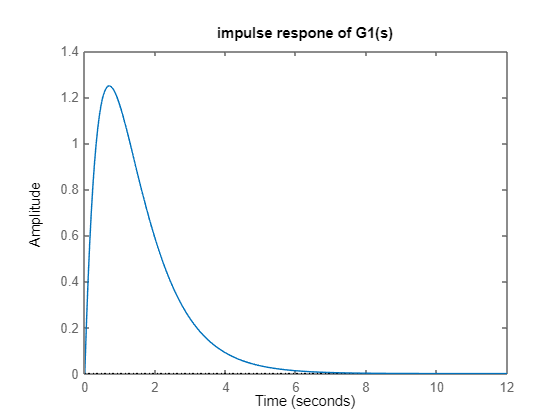


figure;
impulse(G1);
title("impulse respone of G1(s)");

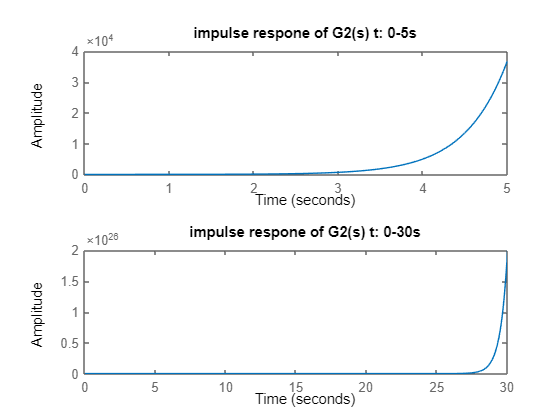


figure;
subplot(2,1,1)
impulse(G2,5);

title("impulse respone of G2(s) t: 0-5s");
subplot(2,1,2)
impulse(G2);

title("impulse respone of G2(s) t: 0-30s");

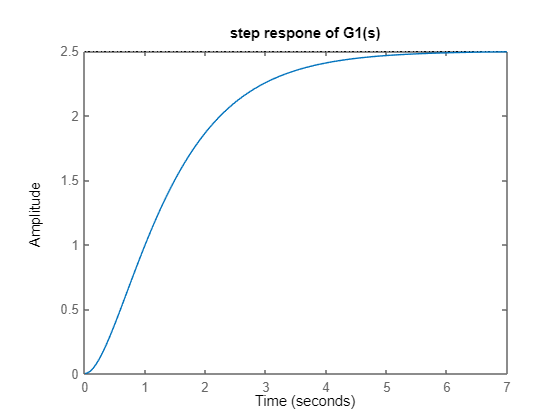

figure;
step(G1);
title("step respone of G1(s)");

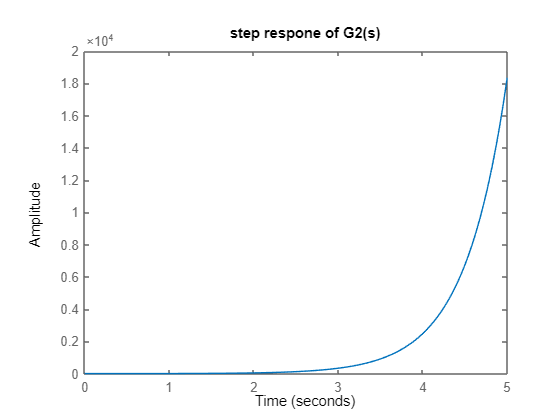


figure;
step(G2,5);
title("step respone of G2(s)");

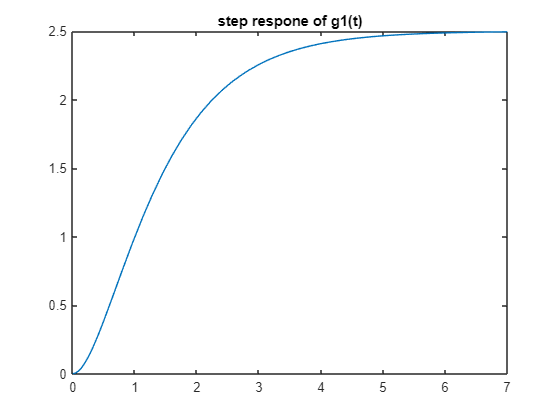


G1S = G1F / s;
G2S = G2F/ s;

g1s = ilaplace(G1S, s, t);
g2s = ilaplace(G2S, s, t);
figure;
fplot(g1s, [0 7])
title("step respone of g1(t)");

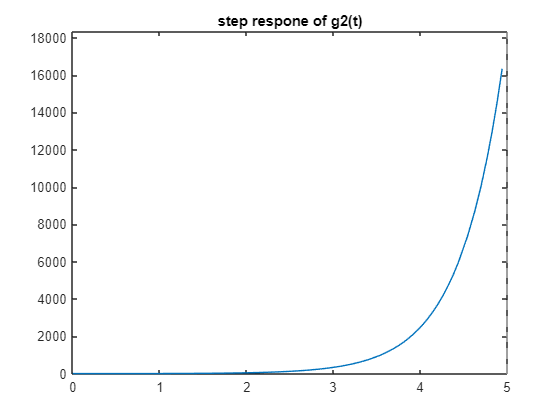


figure;
fplot(g2s, [0 5])
title("step respone of g2(t)");